# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `layers`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 16-Jul-2020 13:27:30

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("C:\Users\pablo\Documents\UNIVERSIDAD\TFG_Neural_Network\MatLab\MisCosas\MatLab-TFG-Neural-Network\trainingSetup_2020_07_16__13_27_23.mat");

## Import Data

Import training and validation data.

imdsTrain = imageDatastore("C:\Users\pablo\Documents\UNIVERSIDAD\TFG_Neural_Network\MatLab\MisCosas\MatLab-TFG-Neural-Network\imgLineaBola","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7);

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([50 50 1],imdsTrain);
augimdsValidation = augmentedImageDatastore([50 50 1],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("sgdm",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",0.01,...
    "Shuffle","every-epoch",...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Array of Layers

layers = [
    imageInputLayer([50 50 1],"Name","imageinput","Normalization","rescale-zero-one")
    convolution2dLayer([3 3],5,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    tanhLayer("Name","relu_1")
    maxPooling2dLayer([3 3],"Name","maxpool","Padding","same")
    fullyConnectedLayer(2,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

% Hay muchas posibilidades aquí, número de filtros y cosas así

## Train Network

Train the network using the specified options and training data.

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:01 |       51.56% |       61.67% |       0.7259 |       0.6198 |          0.0100 |


|      30 |          30 |       00:00:07 |      100.00% |      100.00% |       0.0002 |       0.0015 |          0.0100 |
|======================================================================================================================|


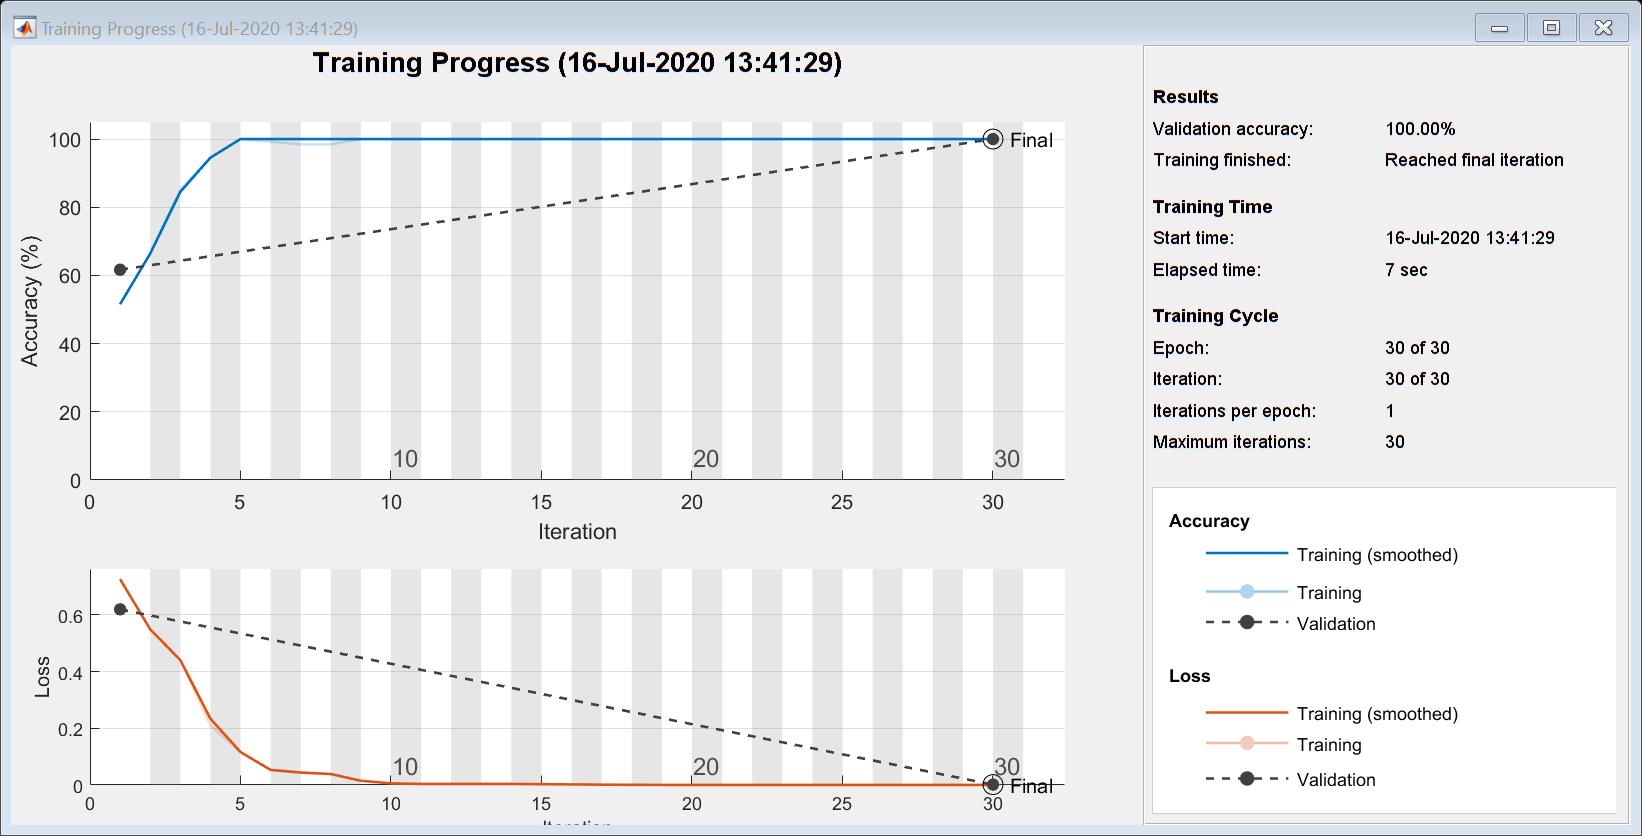

[net, traininfo] = trainNetwork(augimdsTrain,layers,opts);

## Comprobación de resultados

[YPred,probs] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 1

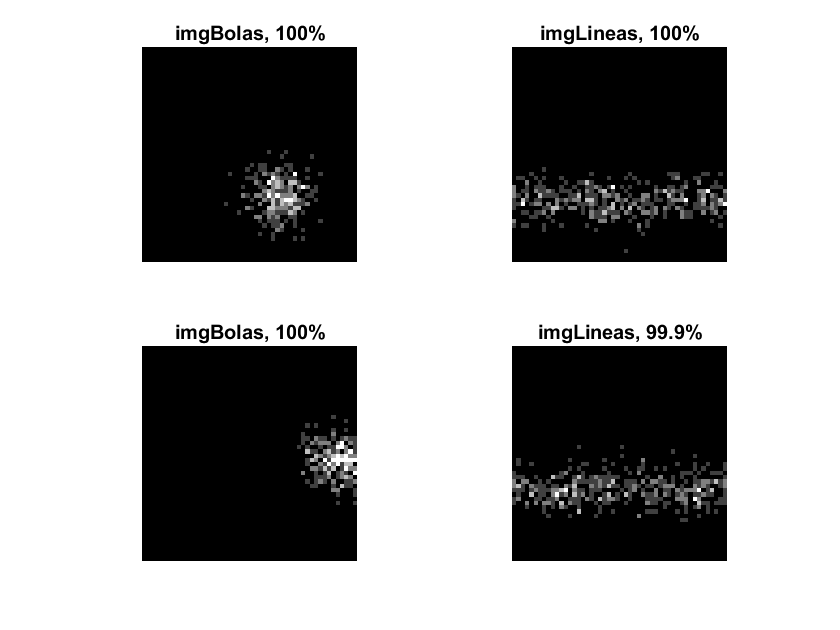


idx = randperm(numel(imdsValidation.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValidation,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end

## Guardar resultados

save LineaBola_deep6 net
